# Analyzing Satellite Images of a Flood

**Import and display the images**

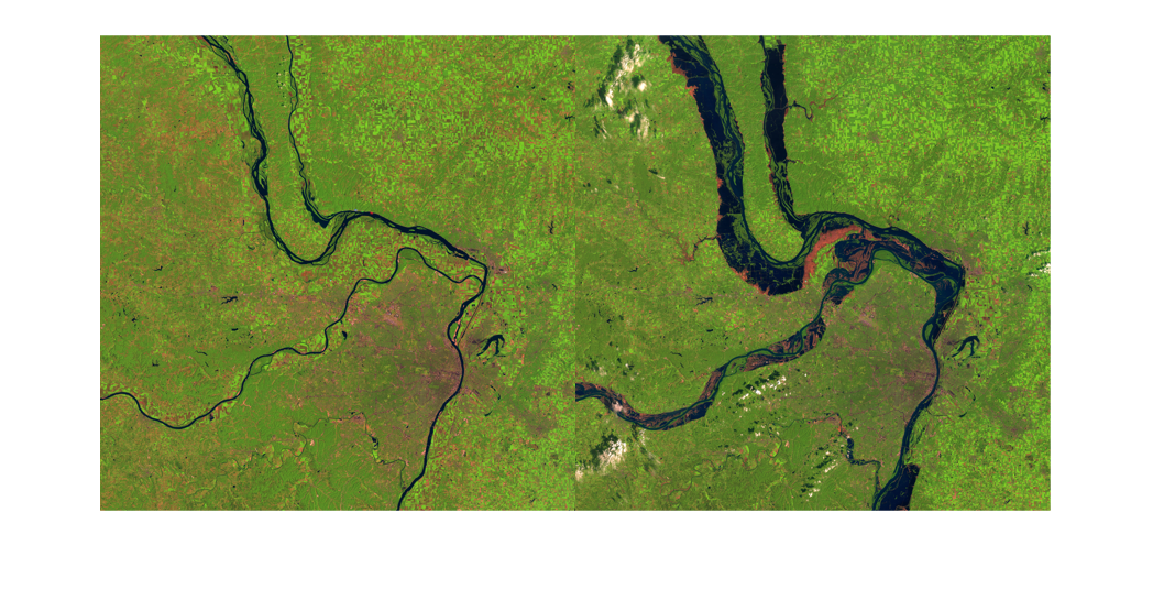

preflood = imread("stlouis_l5tm_14aug91_30m.jpg");
postflood = imread("stlouis_l5tm_19aug93_30m.jpg");
montage({preflood,postflood})

### Color thresholding

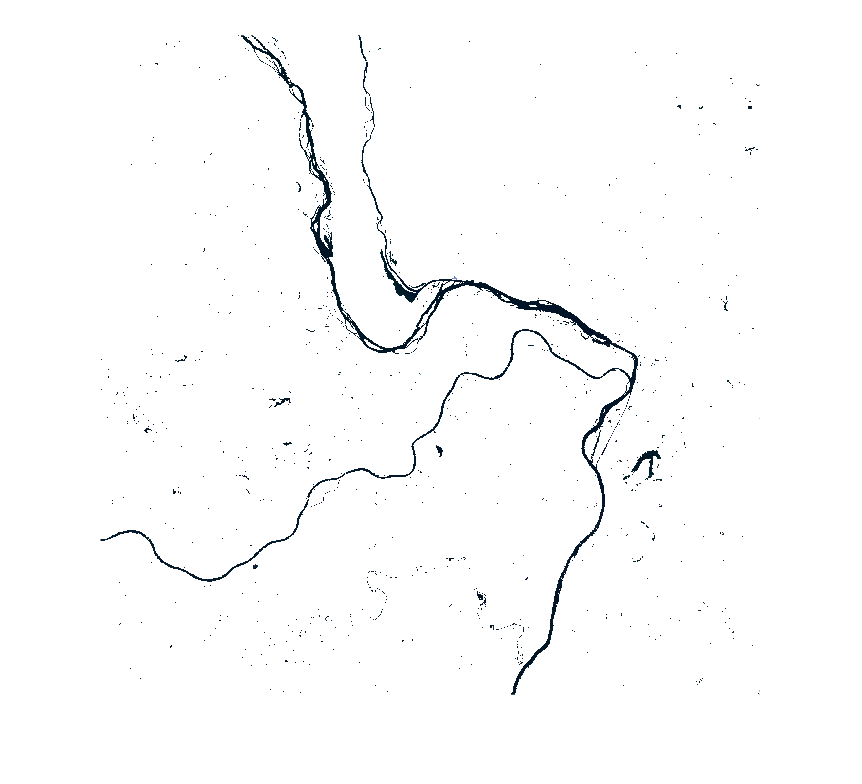

[BWpre, maskpre] = segmentflood(preflood);
imshow(maskpre)

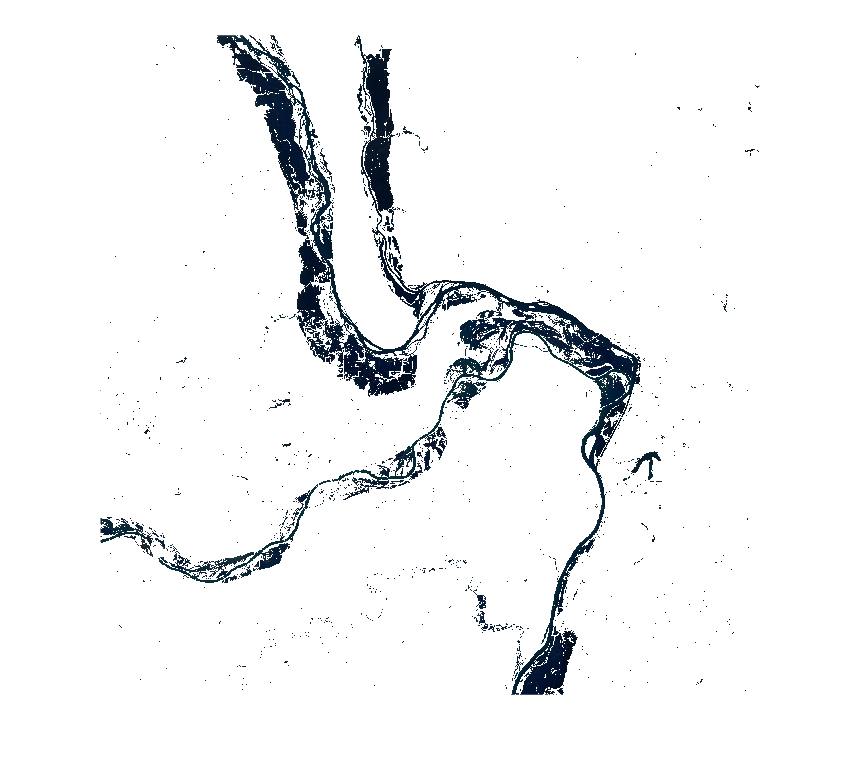

[BWpost, maskpost] = segmentflood(postflood);
imshow(maskpost)

### Numerical analysis

Use the segmentation function outputs and the `nnz` function to calculate the number of blue river pixels in each image. 

The nnz determines the number of non zero pixels on matrix. 

nnz(BWpre)

ans = 284438

nnz(BWpost)

ans = 1070266

Calculate the increase in pixel values between the first and second images.

(nnz(BWpost) - nnz(BWpre)) / nnz(BWpre) * 100

ans = 276.2739

We are seeing a value of around 277%. That's a huge increase in water area due to the flood! 